y = [0.1, 0.2, 2, 4.5, 6.8, 9.1, 10.3, 11.4, 12.9, 42.7]/100;
x = [1,2,3,4,5,6,7,8,9,10];
xn = randsrc(1000000,1,[x; y]);
pd = fitdist(xn,'Kernel','Kernel','Epanechnikov');
x_values = 0:1:10

x_values =      0     1     2     3     4     5     6     7     8     9    10


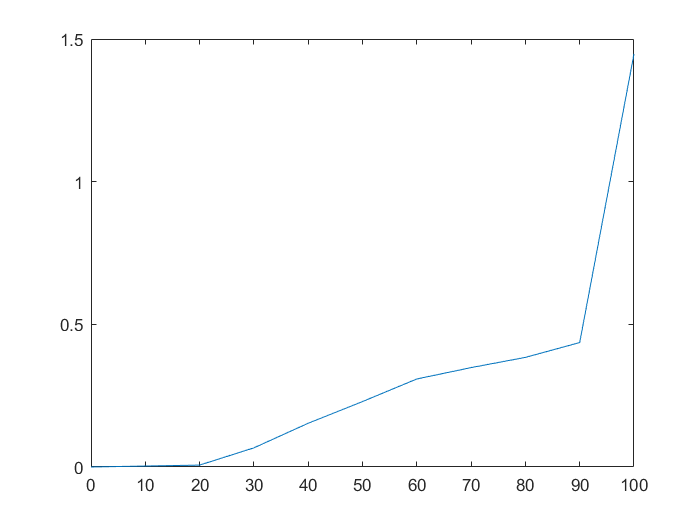

yi = pdf(pd,x_values);
plot(x_values * 10,yi);

data = pd.random(1,100000) * 10;
eval('data')

data =   101.1456   98.0654   99.1924  101.2829   49.7375   78.5413   39.5496   99.5197  100.8919   60.2113   49.8962   81.3108   99.8717   89.3764   90.4184  101.1468   98.2996  100.0599   28.4420   88.9410   58.9449   70.2701   39.6093   88.8856   60.8204  101.4042   49.8500   80.8657  100.3118   98.4254  101.6484   30.2018  101.0326   69.2300  100.0148  101.3558   99.9655   62.0786   91.0369   38.6090  101.1316   51.9193   90.7977   90.1669   50.4809   78.7042   80.3644  101.4932   48.7126   98.4654


eval('pd')

pd =   KernelDistribution

    Kernel = epanechnikov
    Bandwidth = 0.0990845
    Support = unbounded


csvwrite('结束SOC.txt', data)